# 先端機械学習 中間課題 Problem1

### Toy Dataset 4

n = 200;
d = 4;
x = 3 * (rand(d, n) - 0.5);
y = (2 * x(1, :) - 1 * x(2 , :) + 0.5 + 0.5 * randn(1, n)) > 0;
y = 2 * y -1;

# 単純な最急降下法

lr = 10.^(-1 .* 2) ;% learning rate: const

w = ones(d,1); % initial param.
lambda =1;
loop = 200;
nab_J_step = @(w,x,y) exp(-y*(w'*x))/(1+exp(-y*(w'*x))) *(-y).*(x);
J_step = @(w,x,y) log(1+exp(-y*(w'*x)));
J_history = zeros(loop,1);
for t = 1:loop
    %Calc. nabla J
    nab_Jstep = zeros(d,1);
    for i=1:n
        nab_Jstep = nab_Jstep + nab_J_step(w,x(:,i),y(:,i));
    end
    w = w - lr .* (nab_Jstep +2.* lambda.*w) ;
    % Calc. J
    Jstep = 0;
    for i=1:n
        Jstep = Jstep + J_step(w,x(:,i),y(:,i));
    end
    J_history(t) = Jstep + lambda * (w'*w);
end
w

w =     2.9119
   -1.3985
   -0.0986
   -0.0167


predict = 2 * (w'* x >0)-1;
fprintf("Accuracy: %.4f",sum(predict==y)/n);

Accuracy: 0.9150

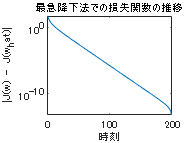

J_history = abs(J_history - J_history(loop) + 1e-18);% 1e-18 : To avoid log(0)
semilogy(J_history(1:loop-1));
title('最急降下法での損失関数の推移')
xlabel('時刻')
ylabel('|J(w) - J(w_hat)|')

# ニュートン法

lr = 10.^(-1 .* 1) ;% learning rate: const

w = ones(d,1); % initial param.
lambda =1;
loop = 200;
H_step = @(w,x,y) exp(-y*(w'*x))/(1+exp(-y*(w'*x)))^2 .*x*x';
nab_J_step = @(w,x,y) exp(-y*(w'*x))/(1+exp(-y*(w'*x))) *(-y).*(x);
J_step = @(w,x,y) log(1+exp(-y*(w'*x)));
J_history = zeros(loop,1);
for t = 1:loop
    % Calc. Nabla J
    nab_Jstep = zeros(d,1);
    for i=1:n
        nab_Jstep = nab_Jstep + nab_J_step(w,x(:,i),y(:,i));
    end
    nab_Jstep = nab_Jstep+2.*lambda.*w;
    % Calc. J
    Jstep = 0;
    for i=1:n
        Jstep = Jstep + J_step(w,x(:,i),y(:,i));
    end
    Jstep = Jstep + lambda* (w'*w);
    J_history(t) = Jstep;
    %Calc. Hessian J
    Hstep = zeros(d,d);
    for i=1:n
        Hstep = Hstep + H_step(w,x(:,i),y(:,i));
    end
    Hstep = Hstep + lambda .* eye(d);
    w = w - lr.* (Hstep\nab_Jstep) ;
end
w

w =     2.9119
   -1.3985
   -0.0986
   -0.0167


predict = 2 * (w'* x >0)-1;
fprintf("Accuracy: %.4f",sum(predict==y)/n);

Accuracy: 0.9150

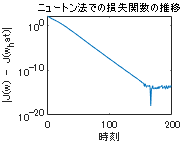

J_history = abs(J_history - J_history(loop) + 1e-18);% 1e-18 : To avoid log(0)
semilogy(J_history(1:loop-1));
title('ニュートン法での損失関数の推移')
xlabel('時刻')
ylabel('|J(w) - J(w_hat)|')

# Multi-class logistic classification

### Toy Dataset 5

n = 200;% data amount
d = 4;% data dimension
c = 3;% class
x = 3 * (rand(n, d) - 0.5);
W = [2, -1, 0.5;
-3, 2, 1;
1, 2, 3];
[maxlogit, y] =max( [x(:, 1:2), ones(n, 1)] * W' + 0.5 * randn(n, c), [], 2);

one-hot enocding

y_onehot = (y == 1:c)*2-1;

# 最急降下法

lr = 10.^(-1 .* 2) ;% learning rate: const
x = x';
y = y';
y_onehot = y_onehot';
w = ones(d,c); % initial param.
lambda =1;
loop = 200;
nab_J_step = @(w,x,y) exp(-y'*(w'*x))/(1+exp(-y'*(w'*x))) *(-y).*(x);
J_step = @(w,x,y) log(1+exp(-y*(w'*x)));
J_history = zeros(loop,c);
for t = 1:loop
    for class = 1:c
        nab_Jstep = zeros(d,1);
        for i=1:n
            nab_Jstep = nab_Jstep + nab_J_step(w(:,class),x(:,i),y_onehot(class,i));
        end
        w(:,class) = w(:,class) - lr .* (nab_Jstep +2.* lambda.*w(:,class)) ;
        Jstep = 0;
        for i=1:n
            Jstep = Jstep + J_step(w(:,class),x(:,i),y_onehot(class,i));
        end
        J_history(t,class) = Jstep + lambda * (w(:,class)'*w(:,class));
    end
end
w

w =     0.8608   -2.5389    1.5346
   -1.3588   -0.2425    1.4240
   -0.0909   -0.3602    0.0999
    0.4857   -0.1777   -0.2348


predict = w'*x;
for t = 1:loop
    [M, I] = max(predict(:,t));
    label = -1 .* ones(1,c);
    label(1,I) = 1;
    predict(:,t) = label(1,:);
end
result = (predict == y_onehot)*1;
fprintf("Accuracy: %.4f \n",sum(result(:))/(c*n));

Accuracy: 0.8633 


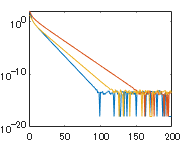

J_history = abs(J_history - J_history(loop,:) + 1e-18.*ones(size(J_history)));% 1e-18 : To avoid log(0)
semilogy(J_history(1:loop-1,1));
hold on
semilogy(J_history(1:loop-1,2));
semilogy(J_history(1:loop-1,3));
hold off

### Toy Dataset 5

n = 200;% data amount
d = 4;% data dimension
c = 3;% class
x = 3 * (rand(n, d) - 0.5);
W = [2, -1, 0.5;
-3, 2, 1;
1, 2, 3];
[maxlogit, y] =max( [x(:, 1:2), ones(n, 1)] * W' + 0.5 * randn(n, c), [], 2);

one-hot enocding

y_onehot = (y == 1:c)*2-1;

# ニュートン法

lr = 10.^(-1 .* 1) ;% learning rate: const
w = ones(d,c); % initial param.
lambda =1;
loop = 200;
H_step = @(w,x,y) exp(-y*(w'*x))/(1+exp(-y*(w'*x)))^2 .*x*x';
nab_J_step = @(w,x,y) exp(-y*(w'*x))/(1+exp(-y*(w'*x))) *(-y).*(x);
J_step = @(w,x,y) log(1+exp(-y*(w'*x)));
J_history = zeros(loop,c);
for t = 1:loop
    for class = 1:c
                % Calc. Nabla J
        nab_Jstep = zeros(d,1);
        for i=1:n
            nab_Jstep = nab_Jstep + nab_J_step(w(:,class),x(i,:)',y_onehot(i,class)');
        end
        nab_Jstep = nab_Jstep+2.*lambda.*w(:,class);
        % Calc. J
        Jstep = 0;
        for i=1:n
            Jstep = Jstep + J_step(w(:,class),x(i,:)',y_onehot(i,class)');
        end
        Jstep = Jstep + lambda* (w(:,class)'*w(:,class));
        J_history(t,class) = Jstep;
        %Calc. Hessian J
        Hstep = zeros(d,d);
        for i=1:n
            Hstep = Hstep + H_step(w(:,class),x(i,:)',y_onehot(i,class)');
        end
        Hstep = Hstep + lambda .* eye(d);
        w(:,class) = w(:,class) - lr.* (Hstep\nab_Jstep) ;
    end

end
w

w =     0.8457   -2.2407    1.4686
   -1.0606    0.2309    1.1862
    0.0092   -0.1408    0.0235
   -0.1542   -0.0397    0.2342


predict = w'*x';
for t = 1:loop
    [M, I] = max(predict(:,t));
    label = -1 .* ones(1,c);
    label(1,I) = 1;
    predict(:,t) = label(1,:);
end
result = (predict' == y_onehot)*1;
fprintf("Accuracy: %.4f",sum(result(:))/(c*n));

Accuracy: 0.8333

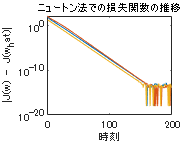

J_history = abs(J_history - J_history(loop,:) + 1e-18);% 1e-18 : To avoid log(0)
semilogy(J_history(1:loop-1,1));
hold on
semilogy(J_history(1:loop-1,2));
semilogy(J_history(1:loop-1,3));
title('ニュートン法での損失関数の推移')
xlabel('時刻')
ylabel('|J(w) - J(w_hat)|')
hold off